reading_brewster = [106.5583 107.5;
    110.0333 105.3;
    118.025 103.9;
    112.525 91.2;
    122.5583 84.5;
    128.0417 71.9
    134.05 59.9;
    137 48.0;
    140.0083 38.6;
    145.0333 33.7;
    145.5333 33.7;
    146 33.7;
    144.025 32.1;
    148.5583 19.8;
    149.55  15.5;
    150.5667 9.4;
    151.0333 7.9;
    152.525 10.5;
    154.0417 12.5;
    156.5667 24.6;
    160.0417 54.9;
    164.5333 88.4;
    168.525 90.4
    ]

reading_brewster =   106.5583  107.5000
  110.0333  105.3000
  118.0250  103.9000
  112.5250   91.2000
  122.5583   84.5000
  128.0417   71.9000
  134.0500   59.9000
  137.0000   48.0000
  140.0083   38.6000
  145.0333   33.7000


reading_s = 
    [107.56 108.5;
    137 78.5;
    160 80;
    170 94.5]

reading_s =   107.5600  108.5000
  137.0000   78.5000
  160.0000   80.0000
  170.0000   94.5000


scatter(reading_brewster(:,1),reading_brewster(:,2),'k')
hold on
[fitResult, gof] = fit(reading_brewster(:,1),reading_brewster(:,2),"poly9")

fitResult =      Linear model Poly9:
     fitResult(x) = p1*x^9 + p2*x^8 + p3*x^7 + p4*x^6 + 
                    p5*x^5 + p6*x^4 + p7*x^3 + p8*x^2 + p9*x + p10
     Coefficients (with 95% confidence bounds):
       p1 =   4.306e-11  (4.696e-12, 8.142e-11)
       p2 =  -5.335e-08  (-1.009e-07, -5.807e-09)
       p3 =   2.927e-05  (3.161e-06, 5.538e-05)
       p4 =   -0.009334  (-0.01767, -0.0009939)
       p5 =       1.907  (0.199, 3.614)
       p6 =      -258.7  (-491, -26.29)
       p7 =   2.331e+04  (2292, 4.433e+04)
       p8 =  -1.345e+06  (-2.564e+06, -1.271e+05)
       p9 =   4.514e+07  (4.062e+06, 8.621e+07)
       p10 =  -6.705e+08  (-1.284e+09, -5.698e+07)

gof = struct with fields:
           sse: 308.0356
       rsquare: 0.9883
           dfe: 13
    adjrsquare: 0.9801
          rmse: 4.8678


plot(fitResult,'k')
ylim([0 110])
xlim([106.5583 170])
scatter(reading_s(:,1),reading_s(:,2),'k')
[fitResult2, gof2] = fit(reading_s(:,1),reading_s(:,2),"poly3")

fitResult2 =      Linear model Poly3:
     fitResult2(x) = p1*x^3 + p2*x^2 + p3*x + p4
     Coefficients:
       p1 =   0.0003409
       p2 =     -0.1172
       p3 =       12.29
       p4 =        -281

gof2 = struct with fields:
           sse: 4.6529e-25
       rsquare: 1
           dfe: 0
    adjrsquare: NaN
          rmse: NaN


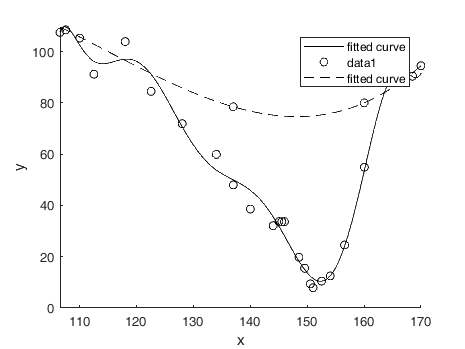

plot(fitResult2,'k--')